clear

% % Reading in the ERA5 COL data
% experiment_names = "ERA5";
% experiment_names2 = "ERA5";
% num_experiments = length(experiment_names);
% ds_names = ["_Rows_Cols_Matrix.csv", "_average_lons.csv", "_adjusted_lons.csv", "_average_lats.csv", "_durations.csv", "_start_tsteps.csv"];
% all_exp_ds_cell = cell(length(ds_names),num_experiments);
% for i = 1:size(all_exp_ds_cell,1)
%     for j = 1:size(all_exp_ds_cell,2)
%         if ds_names(i) == "_adjusted_lons.csv"
%             tmp_ds_nm = experiment_names(j) + "/" + experiment_names(j) + "_average_lons.csv";
%             tmp_lons = readmatrix(tmp_ds_nm);
%             all_exp_ds_cell{i,j} = cat(1,tmp_lons,tmp_lons(tmp_lons<10)+350,tmp_lons(tmp_lons>350)-350);
%         else
%             tmp_ds_nm = experiment_names(j) + "/" + experiment_names(j) + ds_names(i);
%             all_exp_ds_cell{i,j} =  readmatrix(tmp_ds_nm);
%         end
%     end
% end
% % The rows = [rcm lon adj_lon lat dur tstep] and cols = ERA5
% % all_exp_ds_cell
% 
% % % % Year, Month, and Day Labeling
% all_timestamps = all_exp_ds_cell{6};
% date_vec = datetime(1990,1,1,0,0,0):.25:datetime(2020,12,31,23,59,0);
% all_timestamps = date_vec(all_timestamps)';
% all_years = year(all_timestamps);
% all_months = month(all_timestamps);
% all_days = day(all_timestamps);
% 
% % % % Longitude / Region Labeling
% pacific_vec = zeros(size(all_timestamps)); % 140 to 235
% west_pac_vec = zeros(size(all_timestamps)); % 140 to 180
% cen_pac_vec = zeros(size(all_timestamps)); % 180 to 220
% east_pac_vec = zeros(size(all_timestamps)); % 220 to 240
% 
% north_america_vec = zeros(size(all_timestamps)); % 240 to 290
% atlantic_vec = zeros(size(all_timestamps)); % 290 to 340
% europe_africa_vec = zeros(size(all_timestamps)); % -20 to 60, so 0 to 60 and then 340 to 360
% asia_vec = zeros(size(all_timestamps)); % 60 to 140
% 
% all_lons = all_exp_ds_cell{2};
% 
% 
% pacific_vec(all_lons>=140 & all_lons<240) = 1;
% west_pac_vec(all_lons>=140 & all_lons<180) = 1;
% cen_pac_vec(all_lons>=180 & all_lons<220) = 1;
% east_pac_vec(all_lons>=220 & all_lons<240) = 1;
% 
% north_america_vec(all_lons>=240 & all_lons<290) = 1;
% atlantic_vec(all_lons>=290 & all_lons<340) = 1;
% europe_africa_vec(all_lons>=340) = 1;
% europe_africa_vec(all_lons<60) = 1;
% asia_vec(all_lons>=60 & all_lons<140) = 1;
% 
% pacific_log = logical(pacific_vec);
% west_pac_log = logical(west_pac_vec);
% cen_pac_log = logical(cen_pac_vec);
% east_pac_log = logical(east_pac_vec);
% 
% north_america_log = logical(north_america_vec);
% atlantic_log = logical(atlantic_vec);
% europe_africa_log = logical(europe_africa_vec);
% asia_log = logical(asia_vec);
% 
% % % % ENSO Labeling
% oni_all = readmatrix("ERA5\ONI.txt","OutputType","string");
% oni_3mon = oni_all(:,1);
% oni_1mon = repmat(1:12,[1 31])';
% oni_year = str2double(oni_all(:,2));
% oni_anom = str2double(oni_all(:,4));
% 
% nino_vec = zeros(size(all_timestamps));
% nina_vec = zeros(size(all_timestamps));
% neut_vec = zeros(size(all_timestamps));
% 
% for i = 1:length(oni_anom)
%     tmp_oni_anom = oni_anom(i);
%     tmp_year = oni_year(i);
%     tmp_month = oni_1mon(i);
%     nino_vec(all_years==tmp_year & all_months==tmp_month) = tmp_oni_anom;
%     nina_vec(all_years==tmp_year & all_months==tmp_month) = tmp_oni_anom;
%     neut_vec(all_years==tmp_year & all_months==tmp_month) = tmp_oni_anom;
% end
% nino_vec(nino_vec<0.5) = 0;
% nina_vec(nina_vec>-0.5) = 0;
% neut_vec(neut_vec<=-0.5) = 0;
% neut_vec(neut_vec>=0.5) = 0;
% 
% nino_log = logical(nino_vec);
% nina_log = logical(nina_vec);
% neut_log = logical(neut_vec);
% 
% % % % PDO Labeling
% pdo_all = readmatrix("ERA5\PDO.txt");
% pdo_all = pdo_all(:,2:end);
% pdo_all = reshape(pdo_all',[size(pdo_all,1)*size(pdo_all,2) 1]);
% pdo_year = oni_year;
% pdo_month = repmat(1:12,[1 31])';
% 
% pos_pdo_vec = zeros(size(all_timestamps)); 
% neg_pdo_vec = zeros(size(all_timestamps)); 
% 
% for i = 1:length(pdo_all)
%     tmp_pdo = pdo_all(i);
%     tmp_year = pdo_year(i);
%     tmp_month = pdo_month(i);
%     pos_pdo_vec(all_years==tmp_year & all_months==tmp_month) = tmp_pdo;
%     neg_pdo_vec(all_years==tmp_year & all_months==tmp_month) = tmp_pdo;
% end
% 
% pos_pdo_vec(pos_pdo_vec<=0) = 0;
% neg_pdo_vec(neg_pdo_vec>0) = 0;
% 
% pos_pdo_log = logical(pos_pdo_vec);
% neg_pdo_log = logical(neg_pdo_vec);
% 
% % % % MJO Labeling
% omi = readmatrix("ERA5\ERA5_OMI.txt");
% omi = [omi(:,1) omi(:,2) omi(:,3) omi(:,6)]; % [year month day phase]
% omi_year = omi(:,1);
% omi_month = omi(:,2);
% omi_day = omi(:,3);
% omi_phase = omi(:,4);
% 
% mjo_vec = zeros(size(all_timestamps));
% 
% for i = 1:length(omi_phase)
%     tmp_omi_phase = omi_phase(i);
%     tmp_year = omi_year(i);
%     tmp_month = omi_month(i);
%     tmp_day = omi_day(i);
% 
%     mjo_vec(all_years==tmp_year & all_months==tmp_month & all_days==tmp_day) = tmp_omi_phase;
% end
% 
% % % % Creating the massive table
% 
% table_varnames = ["Avg_Lon" "Avg_Lat" "Duration" "Datetimes" "Year" "Month"...
%                   "Pacific" "West_Pacific" "Central_Pacific" "East_Pacific" "North_America" "Atlantic" "Europe_and_Africa" "Asia"...
%                   "El_Nino" "La_Nina" "Neutral" "Positive_PDO" "Negative_PDO" "MJO_Phase"];
% 
% all_lons = all_exp_ds_cell{2};
% all_lats = all_exp_ds_cell{4};
% all_durations = all_exp_ds_cell{5};
% 
% col_table = table(all_lons, all_lats, all_durations, all_timestamps,...
%                   all_years, all_months, pacific_log, west_pac_log, cen_pac_log, east_pac_log, north_america_log, atlantic_log, europe_africa_log, asia_log,...
%                   nino_log, nina_log, neut_log, pos_pdo_log, neg_pdo_log, mjo_vec, 'VariableNames', table_varnames);

% % writetable(col_table,"ERA5\ERA5_COL_Table.csv");
col_table = readtable("ERA5\ERA5_COL_Table.csv")

col_table = 24000×20 table
    Avg_Lon    Avg_Lat    Duration         Datetimes          Year    Month    Pacific    West_Pacific    Central_Pacific    East_Pacific    North_America    Atlantic    Europe_and_Africa    Asia    El_Nino    La_Nina    Neutral    Positive_PDO    Negative_PDO    MJO_Phase
    _______    _______    ________    ____________________    ____    _____    _______    ____________    _______________    ____________    _____________    ______

% summary(col_table)

% Data exploration

idx_cen_pac_nino = find(col_table.Central_Pacific==1 & col_table.El_Nino==1)

idx_cen_pac_nino =         1068
        1070
        1072
        1073
        1082
        1083
        1087
        1104
        1115
        1125


idx_cen_pac_nina = find(col_table.Central_Pacific==1 & col_table.La_Nina==1)

idx_cen_pac_nina =         4393
        4409
        4461
        4462
        4468
        4471
        4477
        4510
        4516
        4517


idx_cen_pac_neut = find(col_table.Central_Pacific==1 & col_table.Neutral==1)

idx_cen_pac_neut =      7
    12
    16
    19
    27
    32
    33
    45
    54
    63


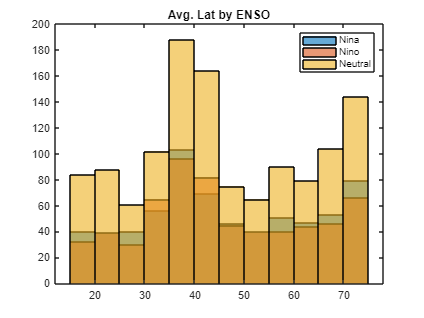


figure;
histogram(table2array(col_table(idx_cen_pac_nina,"Avg_Lat")))
hold on
histogram(table2array(col_table(idx_cen_pac_nino,"Avg_Lat")))
histogram(table2array(col_table(idx_cen_pac_neut,"Avg_Lat")))
hold off
title("Avg. Lat by ENSO")
legend(["Nina" "Nino" "Neutral"])

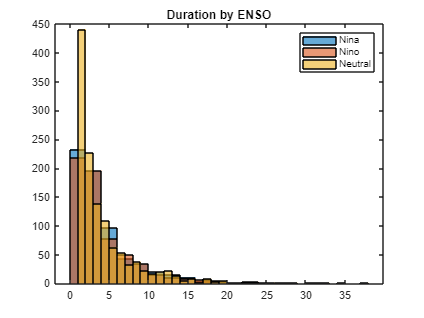


figure;
histogram(table2array(col_table(idx_cen_pac_nina,"Duration"))/4)
hold on
histogram(table2array(col_table(idx_cen_pac_nino,"Duration"))/4)
histogram(table2array(col_table(idx_cen_pac_neut,"Duration"))/4)
hold off
title("Duration by ENSO")
legend(["Nina" "Nino" "Neutral"])


% pac_col_table = col_table(find(col_table.Pacific),:);
% pac_nino_col_table = pac_col_table(find(pac_col_table.El_Nino==1),:);
% pac_nina_col_table = pac_col_table(find(pac_col_table.La_Nina==1),:);
% pac_neut_col_table = pac_col_table(find(pac_col_table.Neutral==1),:);
% 
% figure;
% title("Pacific COLs")
% scatter(pac_nino_col_table,"Datetimes","Duration","filled",MarkerFaceColor='r')
% hold on
% scatter(pac_nina_col_table,"Datetimes","Duration","filled",MarkerFaceColor='b')
% % scatter(pac_neut_col_table,"Datetimes","Duration","filled",MarkerFaceColor='k')
% hold off
% legend(["El Nino" "La Nina" "Neutral"],Location="best")
% 
% figure;
% title("Pacific COLs")
% scatter(pac_nino_col_table,"Datetimes","Avg_Lat","filled",MarkerFaceColor='r')
% hold on
% scatter(pac_nina_col_table,"Datetimes","Avg_Lat","filled",MarkerFaceColor='b')
% scatter(pac_neut_col_table,"Datetimes","Avg_Lat","filled",MarkerFaceColor='k')
% hold off
% legend(["El Nino" "La Nina" "Neutral"],Location="northeast")